# Extract epoch-level features

Sam Michalka

This script will help you extract features for machine learning from EEG data that has already been preprocessed and epoched. It stores the data in a Matlab table, which can then be written to a csv or used to do ML in Matlab. 

In the case of Ted's VR experiment, each epoch is actually a subtrial, and the trials have a variable number of subtrials. This code takes the mean of all the subtrials within a trial to calculate the value for that trial. However, you could also do classification on each subtrial instead of each trial by using the epoch-level data.

## Set up your data and parameters

This code requires that you have eeglab installed to do frequency power extraction (you could do this with regular matlab commands like pwelch instead if you want). The line below checks to see if it is already open, and if not, it starts eeglab.

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "PICARD" v1.0 to the path
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "cleanline-master" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "fieldtrip-" v20230427 to the path
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)
EEGLAB: adding "limo_tools-master" v3.3 (see >> help eegplugin_limo)
EEGLAB: adding "reorder19Channels" v0.11 (see >> help eegplugin_reorder19Channels)


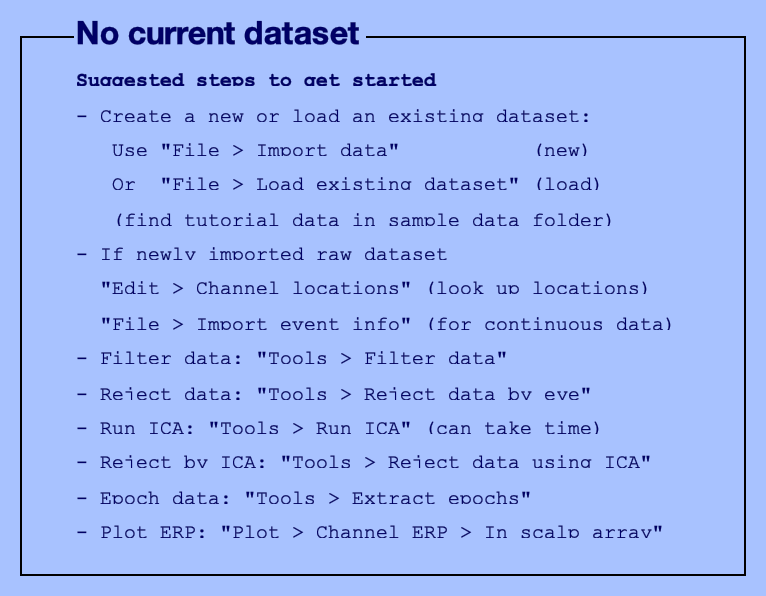

You are using the latest version of EEGLAB.


if ~exist('pop_loadset') || ~exist("ALLEEG",'var') %#ok<EXIST>
    [ALLEEG EEG CURRENTSET ALLCOM] = eeglab;
end 

For frequency band analysis, we list the desired frequency bands here. You can edit this to exclude some bands if you're not interested in them.

freqBands = table(["delta","theta","alpha","beta","lowerAlpha","upperAlpha","lowerBeta","upperBeta"]',...
    [1 4 8 12.5 8 10 12.5 20]', ...
    [4 8 13 30 11 13 20 30]','VariableNames',{'Names','LowFreq','HighFreq'})

freqBands = 8×3 table
       Names        LowFreq    HighFreq
    ____________    _______    ________

    "delta"             1          4   
    "theta"             4          8   
    "alpha"             8         13   
    "beta"           12.5         30   
    "lowerAlpha"        8         11   
    "upperAlpha"       10         13   
    "lowerBeta"      12.5         20   
    "upperBeta"        20         30   


Create a list of all of the files that you want to include in your analysis. This expects one .set file per subject. Change the stuff in "" to match your file location and names. The * allows you to list all the files of a certain type.

lsout = dir("epochedEEG/A*.set"); % all subjects

## Extract all of the values for each subject and put in a table

This is the main code and will take a little while to run. If you want to just test it on one or two people, you can change the line below to "for s = 1:2"

for s = 1:length(lsout)
    EEG = pop_loadset(fullfile(lsout(s).folder,lsout(s).name));
    
    bintags = getBinTags(EEG)

     
    % Extract the spectopo values for each trial
    allfreqs = [];
    badtrials = [];
    uniqueTrials = unique(bintags.trial);
    % The output number of frequencies is 103 by default, so it's hard
    % coded in here. You may need to change this for other data.
    spectraByEpoch = zeros(size(EEG.data,1),103,size(EEG.data,3)); % channels, frequencies, epochs
    absolutePowerByEpoch = zeros(size(EEG.data,1),height(freqBands),size(EEG.data,3)); % channels, bands, epochs



Loop through each epoch and calcuate the absolute power

    for ut = 1:size(EEG.data,3)



Calcuate the absolute power for each epoch

       [spectra,freqs] =  spectopo(EEG.data(:,14:end,ut),0,EEG.srate,'freqrange',[1 30],'plot','off');

       absolutePowerByEpoch(:,:,ut) = getAbsolutePower(spectra,freqs,freqBands);
       spectraByEpoch(:,:,ut) = spectra;


Store the epoch-level data in a table, which will then be combined with other tables. [There are more efficient ways to write this, but this works for now.]

        % Put these into a table
        temptbl  = array2table(absolutePowerByEpoch(:,:,ut),"VariableNames",freqBands.Names);
        %temptbl.id = s .* ones(height(temptbl),1); 
        temptbl.id = repmat(EEG.subject,height(temptbl),1);
        temptbl.channel = (1:size(EEG.data,1))';
        temptbl.epoch = ut  .* ones(height(temptbl),1);
        temptbl.trial = bintags.trial(ut) .* ones(height(temptbl),1);
        temptbl.estimatedSubtrial = bintags.estimatedSubTrial(ut) .* ones(height(temptbl),1);
        temptbl.numTiles = (bintags.B(ut)+2) .* ones(height(temptbl),1);


Here is where to put other code to extract more features from each epoch.  The shape of this data should be channels x 1 for a single feature. You can then add it to the table by:

temptbl.myfeature = myValues; % where my values are ch x 1.

You can also do this in more complex ways if desired.

Make a table for the current subject and concatenate epoch after epoch to store the data.

        if ut == 1
            subjtbl = temptbl;
        else
            % concatenate the tables
            subjtbl = [subjtbl; temptbl];
        end

    end

Store the data in a large table for every subject and epoch.

    if s == 1
        epoch_data = subjtbl;
    else
        epoch_data = [epoch_data; subjtbl];
    end
    
end

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A07_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A07_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [236×1 double]
                trial: [236×1 double]
    estimatedSubTrial: [236×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A08_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A08_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [215×1 double]
                trial: [215×1 double]
    estimatedSubTrial: [215×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A10_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A10_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [201×1 double]
                trial: [201×1 double]
    estimatedSubTrial: [201×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A11_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A11_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [190×1 double]
                trial: [190×1 double]
    estimatedSubTrial: [190×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A13_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A13_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [269×1 double]
                trial: [269×1 double]
    estimatedSubTrial: [269×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A14_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A14_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [295×1 double]
                trial: [295×1 double]
    estimatedSubTrial: [295×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A16_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A16_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [214×1 double]
                trial: [214×1 double]
    estimatedSubTrial: [214×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A17_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A17_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [229×1 double]
                trial: [229×1 double]
    estimatedSubTrial: [229×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A18_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A18_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [196×1 double]
                trial: [196×1 double]
    estimatedSubTrial: [196×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A19_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A19_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [183×1 double]
                trial: [183×1 double]
    estimatedSubTrial: [183×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A20_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A20_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [170×1 double]
                trial: [170×1 double]
    estimatedSubTrial: [170×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A21_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A21_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [158×1 double]
                trial: [158×1 double]
    estimatedSubTrial: [158×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A24_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A24_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [154×1 double]
                trial: [154×1 double]
    estimatedSubTrial: [154×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A25_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A25_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [197×1 double]
                trial: [197×1 double]
    estimatedSubTrial: [197×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A26_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A26_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [295×1 double]
                trial: [295×1 double]
    estimatedSubTrial: [295×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A27_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A27_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [236×1 double]
                trial: [236×1 double]
    estimatedSubTrial: [236×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

pop_loadset(): loading file /Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A28_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.set ...


Reading float file '/Users/smichalka/Documents/Research/VRfreqStats/epochedEEG/A28_rerefrence_elist_256_0.1hz_50hz_ICA_rrrICA_upelist_bins_baseline800_ar.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


bintags = struct with fields:
                    B: [140×1 double]
                trial: [140×1 double]
    estimatedSubTrial: [140×1 double]


Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205; overlap 0):
..................
Computing spectra (window length 205; fft length: 205;

### Summarize by trials 

You can use a table to do group stats on 


trial_data = grpstats(epoch_data,["id","trial","channel","numTiles"],...
    ["mean"],"DataVars",["delta","theta","alpha","beta","lowerAlpha","upperAlpha","lowerBeta","upperBeta"])

trial_data = 21402×13 table
                  id     trial    channel    numTiles    GroupCount    mean_delta    mean_theta    mean_alpha    mean_beta    mean_lowerAlpha    mean_upperAlpha    mean_lowerBeta    mean_upperBeta
                  ___    _____    _______    ________    __________    __________    __________    __________    _________    _______________    _______________    ______________    ______________

    A07_1_1_3     A07      1         1          3            3           2.4692        1.4817        1.6885       0.34

### Save Trial Data to CSV

writetable(trial_data,"VRPlayMeBackMLFeatures.csv")

# Helper functions

### Get Bin Tags: Information about how each epoch/bin relates to the trial structure

The bintags are just a list of each epoch and which trial and condition the epoch belongs in. We also do an estimate of the order within the trial a particular subtrial is in; however, this is not entirely accurate because it doesn't account for missing subtrials. For example, if there were 3 subtrials (a 3 tile sequence) but one subtrial/epoch was rejected, then we wouldn't know if the actual tile order of the remaining two trials was 1 2, 2 3, or 1 3. If this ends up mattering, you can go back and write code to fix it.

The rest of this code is to deal with the fact that a few of the epochs for some subjects have some weird text formatting that results in two cells appearing to describe the epoch instead of just one. Instead of throwing the data out, we fix the text formatting.

function [bintags] = getBinTags(EEG)
    bintags.B = zeros(EEG.trials,1);
    bintags.trial = zeros(EEG.trials,1);
    bintags.estimatedSubTrial = zeros(EEG.trials,1);
    % Extract the trial and condition labels 
    for b = 1:EEG.trials
        binlabels = EEG.epoch(b).eventbinlabel; %bin labels to be parsed
        % Some of the subjects have weird marker formats (where it puts
        % the markers into two cells, sometimes the first one is the
        % correct one and somethings the second cell is the correct one.
        % This code picks the right one.
        if iscell(binlabels)
            if size(binlabels,2) > 1
                % choose the correct bin
                if binlabels{1}(1) == 'B'
                    bintouse = 1;
                else
                    bintouse = 2;
                end
            else
                bintouse = 1;
            end
            bintags.B(b) = str2double(binlabels{bintouse}(2));
            tempcell = extractBetween(binlabels{bintouse},"(_","_");
            bintags.trial(b) = str2double(tempcell{1}); 
        else
            bintags.B(b) = str2double(binlabels(2));
            tempcell = extractBetween(binlabels,"(_","_");
            bintags.trial(b) = str2double(tempcell{1}); 
        end 

        % Put in a subtrial counter
        if b == 1
            lastTrialVal = bintags.trial(b); % first trial number
            bintags.estimatedSubTrial(b) = 1; %start counting at 1       

        % If the current trial matches the last, iterate on the last value
        elseif bintags.trial(b) == lastTrialVal
            bintags.estimatedSubTrial(b) = bintags.estimatedSubTrial(b-1) + 1;
        else
            bintags.estimatedSubTrial(b) = 1;
            lastTrialVal = bintags.trial(b); % Reset the trial counter 

        end
    end
end
    

### Calculate absolute power from the spectra for frequency bands of interest. 

function [absolutePower] = getAbsolutePower(spectra,freqs,freqBands)
% Put in a 2d spectra (ch x freqs), get out 2d matrix of ch x bandpowers
    absolutePower = zeros(size(spectra,1),height(freqBands));
    for b = 1:height(freqBands)
        % find the index of the frequencies between those values
        % (non-inclusive)
        freqIdx = find(freqs> freqBands.LowFreq(b) & freqs<freqBands.HighFreq(b));
        if isempty(freqIdx)
            !warning("No frequencies fall within the range, make band larger. It is non-inclusive.")
        end
        % Convert spectra to mean absolute power 
        if size(size(spectra),2) == 2
            absolutePower(:,b) = mean(10.^(spectra(:,freqIdx)/10),2);
        elseif size(size(spectra),2) == 3

        else
            !warning("Too many dimensions bro")
        end
    end
end